# Redes Neuronales

# Aprendizaje no Supervisado

# Tarea 9

# Dataset Aggregation

**Realizado por: **David Fabián Cevallos Salas

**Fecha: **2023-08-29

tic
clc;
clear;
close all;
rng(0);
warning("off","all");

% Carga y limpieza de datos
datos = importdata("aggregation.txt");
X = datos(:,1:2);

% ---------------------------------------
% k-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-means")

k-means

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 7

k = 7

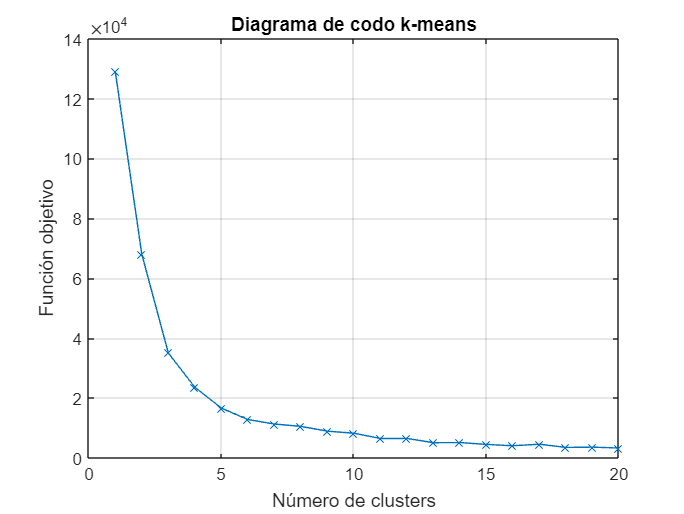

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    Jkm(i) = sum(SumD);
    Kkm(i) = i;
end

figure;
plot(Kkm, Jkm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

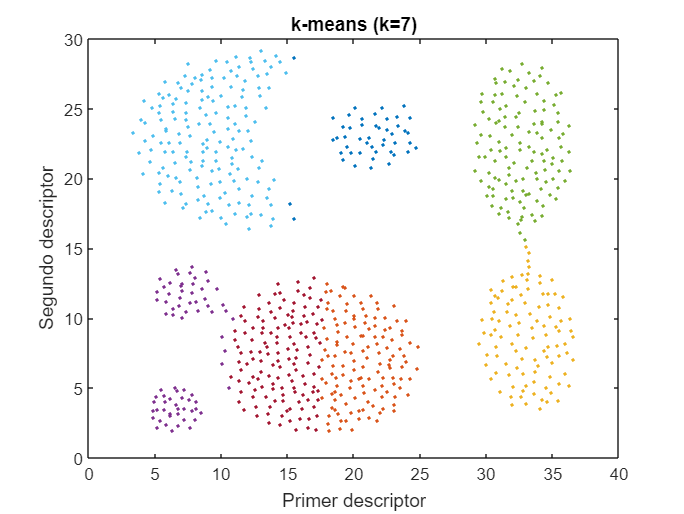


% Clustering
idx = kmeans(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-means (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-means")

Valores de métricas k-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 3.4442

SSB = 11.8195

WB = 2.0398

SIL = 0.6613



% ---------------------------------------
% k-medoids
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-medoids")

k-medoids

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 7

k = 7

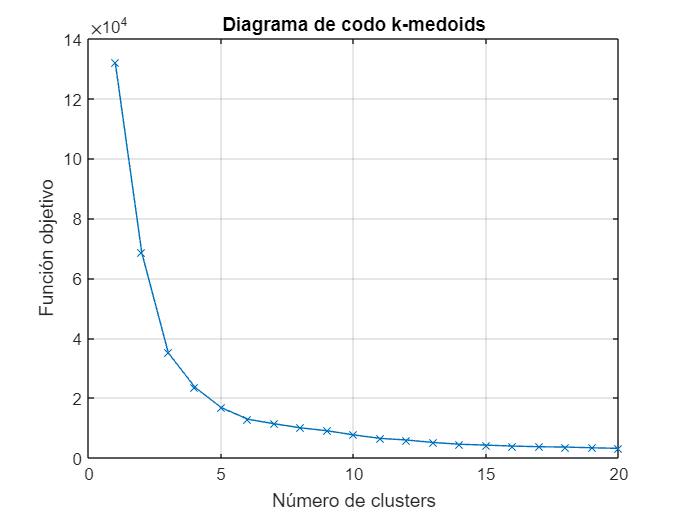

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    Jkmd(i) = sum(SumD);
    Kkmd(i) = i;
end

figure;
plot(Kkmd, Jkmd,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

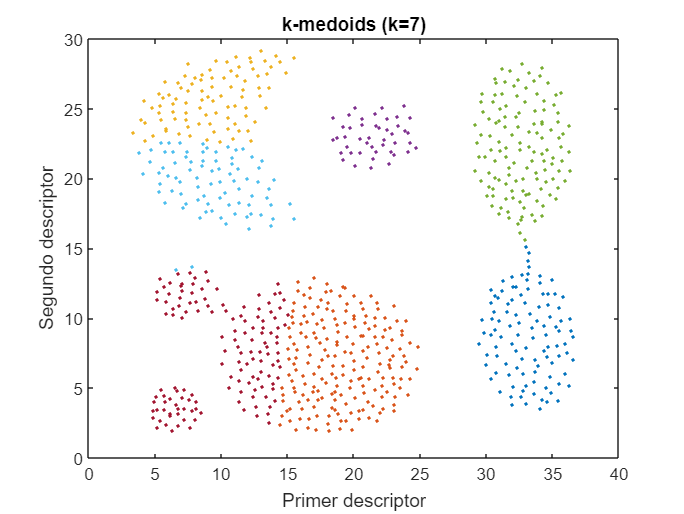


% Clustering
idx = kmedoids(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-medoids (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-medoids")

Valores de métricas k-medoids

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 3.4888

SSB = 11.7849

WB = 2.0723

SIL = 0.6521


% ---------------------------------------
% DBSCAN
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("DBSCAN")

DBSCAN

fprintf("---------------------------------------")

---------------------------------------

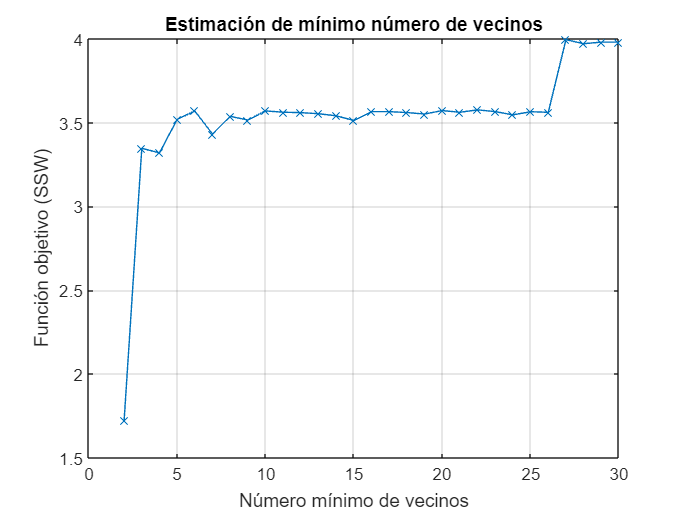


min_n = 15;
gmin_n = 2:1:30;

% Estimación número mínimo de vecinos
for i = 1:length(gmin_n)
    rng(0);
    min_ng = gmin_n(i);
    ep = clusterDBSCAN.estimateEpsilon(X,min_ng,min_ng);
    idx = dbscan(X,ep,min_ng);
    [SSWdb(i) SSBdb(i) WBdb(i) SILdb(i)] = MetricasNoSupervisado(X(idx>0,:),idx(idx>0));
    Kdb(i)=min_ng;
end

figure;
plot(Kdb,SSWdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (SSW)");
title("Estimación de mínimo número de vecinos");

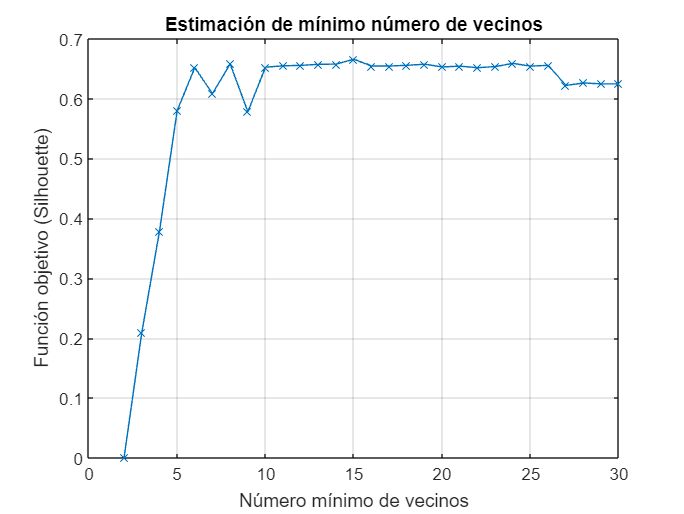


figure;
plot(Kdb,SILdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (Silhouette)");
title("Estimación de mínimo número de vecinos");



% Gráfica k-NN (Nearest Neigbor)
min_n

min_n = 15

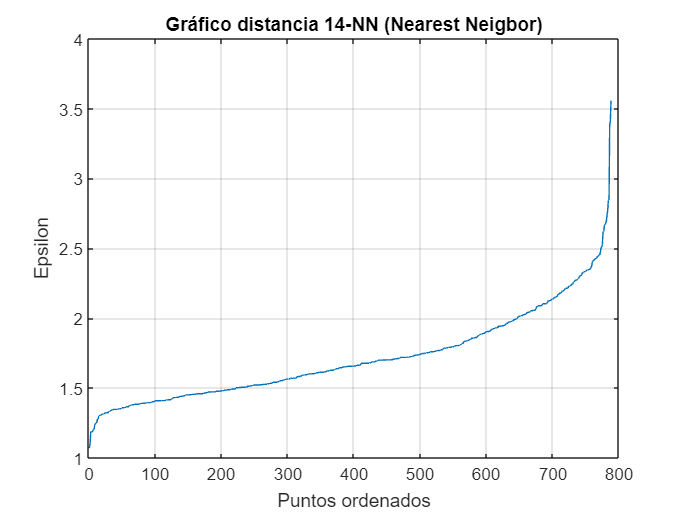

figure;
kD = pdist2(X,X,'euc','Smallest',min_n-1);
plot(sort(kD(end,:)));
title(strcat("Gráfico distancia ",string(min_n-1),"-NN (Nearest Neigbor)"));
xlabel("Puntos ordenados");
ylabel("Epsilon");
grid;


% Clustering
rng(0);
ep = clusterDBSCAN.estimateEpsilon(X,min_n,min_n)

ep = 1.8200

idx = dbscan(X,ep,min_n);
clusters = unique(idx(idx>0));
num_clusters = length(clusters)

num_clusters = 7

anomalias = length(idx(idx<=0));

if (anomalias>0)
    fprintf(strcat("Existen ",string(anomalias)," anomalías"));
else
    fprintf("No existen anomalías");
end

Existen 21 anomalías

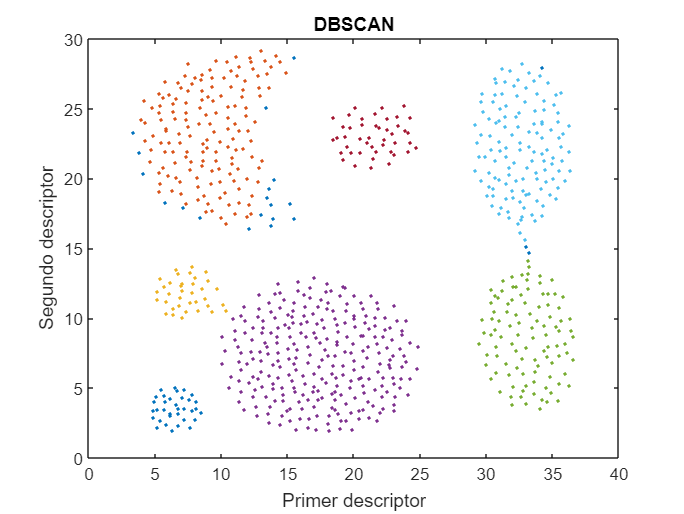


% Visualización de datos
figure;
for i=min(idx):max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("DBSCAN"));


% Métricas
fprintf("Valores de métricas DBSCAN")

Valores de métricas DBSCAN

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(idx>0,:),idx(idx>0))

SSW = 3.5124

SSB = 11.6671

WB = 2.1074

SIL = 0.6658


% ---------------------------------------
% Clustering Jerárquico
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Clustering Jerárquico")

Clustering Jerárquico

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 7

k = 7

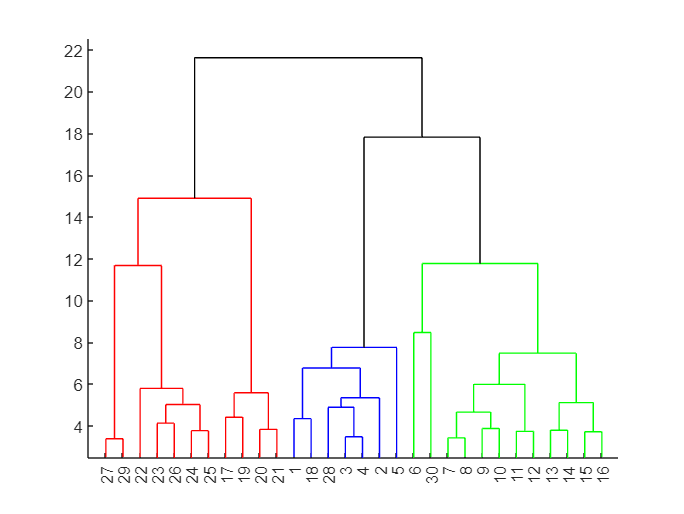

rng(0);

% Dendrograma
tree = linkage(X,"average","euclidean");
figure;
dendrogram(tree,"ColorThreshold","default")

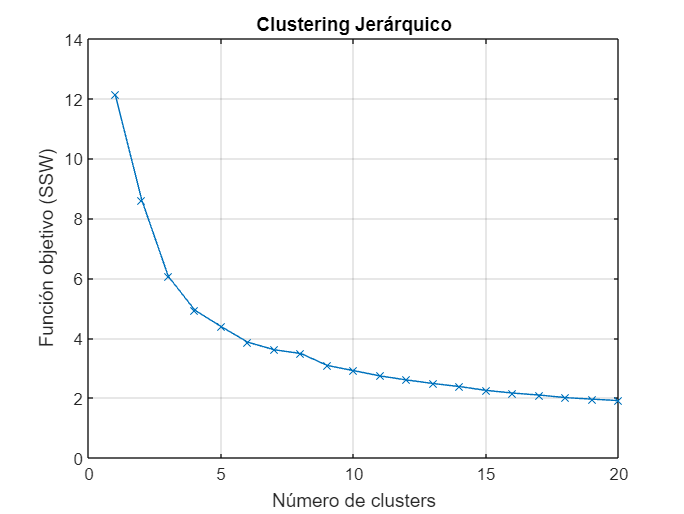


% Diagrama de codo
for i =1:n
    idx = cluster(tree,"maxclust",i);
    [SSWhc(i) SSBhc(i) WBhc(i) SILhc(i)] = MetricasNoSupervisado(X,idx);
    Khc(i)=i;
end

figure;
plot(Khc,SSWhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Clustering Jerárquico");

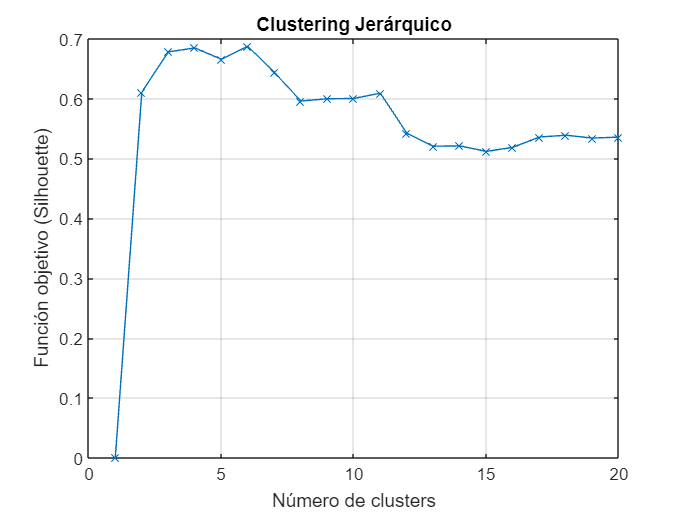


figure;
plot(Khc,SILhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (Silhouette)");
title("Clustering Jerárquico");

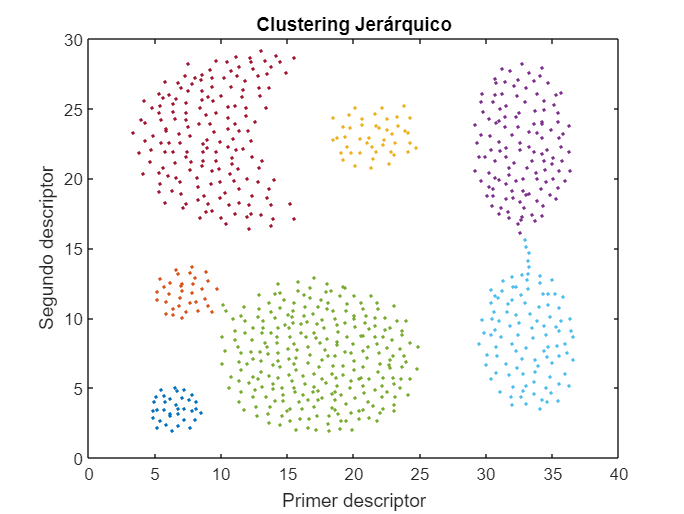


% Clusterización
idx = cluster(tree,"maxclust",k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title("Clustering Jerárquico");


% Métricas
fprintf("Valores de métricas Clustering Jerárquico")

Valores de métricas Clustering Jerárquico

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 3.6068

SSB = 11.6411

WB = 2.1688

SIL = 0.6439


% ---------------------------------------
% Fuzzy c-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Fuzzy c-means")

Fuzzy c-means

fprintf("---------------------------------------")

---------------------------------------


n=20

n = 20

c=7

c = 7

rng(0);

% Diagrama de codo
for i =1:n
    [centers,U] = fcm(X,i);
    Ut=U';
    idx= ones(length(Ut),1);
    maxU = max(U)';

    for j = 1:i
        s = Ut(:,j);
        f = find(s==maxU);
        idx(f)=j;
    end

    [SSWfcm(i) SSBfcm(i) WBfcm(i) SILfcm(i)] = MetricasNoSupervisado(X,idx);
    Kfcm(i)=i;
end

Iteration count = 1, obj. fcn = 0.280822
Iteration count = 2, obj. fcn = 0.073244
Iteration count = 3, obj. fcn = 0.013962
Iteration count = 4, obj. fcn = 0.000016
Iteration count = 5, obj. fcn = 0.000000
Iteration count = 6, obj. fcn = 0.000000
Minimum improvement reached.
Iteration count = 1, obj. fcn = 78247.224166
Iteration count = 2, obj. fcn = 64227.151653
Iteration count = 3, obj. fcn = 63520.954178
Iteration count = 4, obj. fcn = 61591.494354
Iteration count = 5, obj. fcn = 58681.434211
Iteration count = 6, obj. fcn = 56591.602143
Iteration count = 7, obj. fcn = 55321.663338
Iteration count = 8, obj. fcn = 54257.213651
Iteration count = 9, obj. fcn = 53359.249166
Iteration count = 10, obj. fcn = 52700.492893
Iteration count = 11, obj. fcn = 52278.142753
Iteration count = 12, obj. fcn = 52031.963581
Iteration count = 13, obj. fcn = 51896.091053
Iteration count = 14, obj. fcn = 51822.960063
Iteration count = 15, obj. fcn = 51783.921480
Iteration count = 16, obj. fcn = 51763.08785

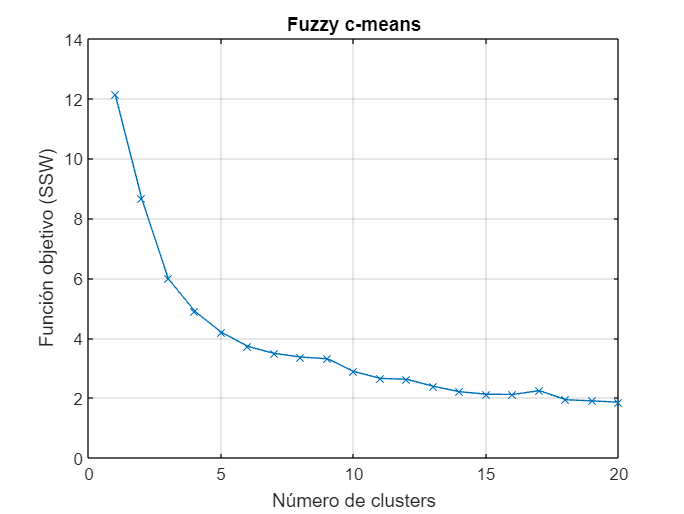


figure;
plot(Kfcm,SSWfcm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Fuzzy c-means");


% Clusterización
[centers,U] = fcm(X,c);

Iteration count = 1, obj. fcn = 24299.623079
Iteration count = 2, obj. fcn = 18367.043898
Iteration count = 3, obj. fcn = 18164.990011
Iteration count = 4, obj. fcn = 17337.618495
Iteration count = 5, obj. fcn = 15055.274074
Iteration count = 6, obj. fcn = 12731.968520
Iteration count = 7, obj. fcn = 11029.314341
Iteration count = 8, obj. fcn = 10058.414887
Iteration count = 9, obj. fcn = 9523.327102
Iteration count = 10, obj. fcn = 8947.669784
Iteration count = 11, obj. fcn = 8013.341848
Iteration count = 12, obj. fcn = 7463.352628
Iteration count = 13, obj. fcn = 7365.899481
Iteration count = 14, obj. fcn = 7331.466276
Iteration count = 15, obj. fcn = 7307.515438
Iteration count = 16, obj. fcn = 7288.908870
Iteration count = 17, obj. fcn = 7274.785708
Iteration count = 18, obj. fcn = 7264.285541
Iteration count = 19, obj. fcn = 7256.268002
Iteration count = 20, obj. fcn = 7249.642461
Iteration count = 21, obj. fcn = 7243.607159
Iteration count = 22, obj. fcn = 7237.683976
Iteration c

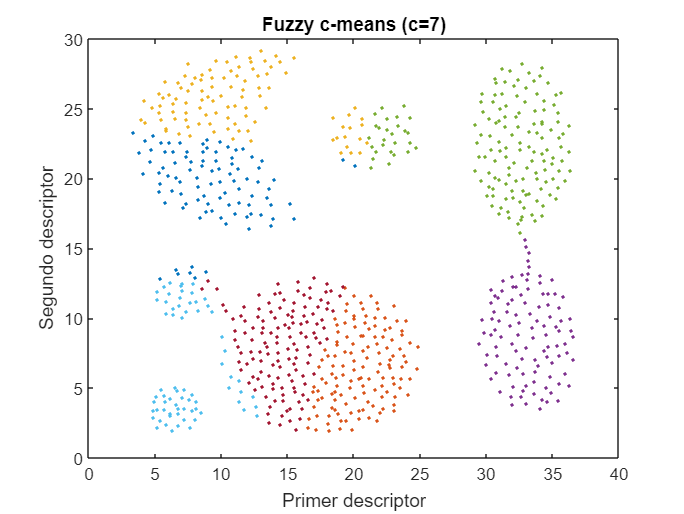

Ut=U';
idx= ones(length(Ut),1);
maxU = max(U)';

for i = 1:c
    s = Ut(:,i);
    f = find(s==maxU);
    idx(f)=i;
end

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("Fuzzy c-means (c=",string(c),")"));


% Métricas
fprintf("Valores de métricas Fuzzy c-means")

Valores de métricas Fuzzy c-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 3.7040

SSB = 11.7384

WB = 2.2088

SIL = 0.5632


toc

Elapsed time is 5.569975 seconds.
